% Load the image (replace 'your_image.jpg' with your file path)
img = imread("C:\Users\teja prakash royal\OneDrive\Desktop\download.jpeg");

% If it's color, convert to grayscale
if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end

% Convert to double for SVD
A = double(img_gray);

% Display original image
figure;
imshow(img_gray);
title('Original Image');

% Compute SVD
[U, S, V] = svd(A);

% S is diagonal; singular values are on the diagonal
singular_values = diag(S);

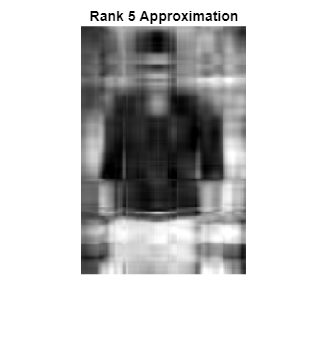

Rank 5: Compression Ratio = 21.9281


Relative Error: 0.19924


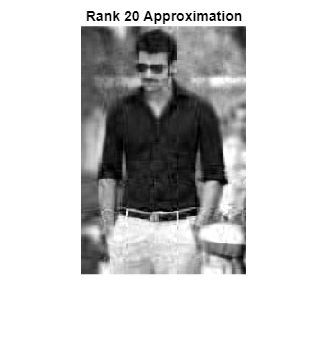

Rank 20: Compression Ratio = 5.482


Relative Error: 0.08525


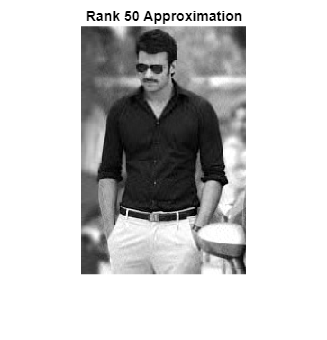

Rank 50: Compression Ratio = 2.1928


Relative Error: 0.036246


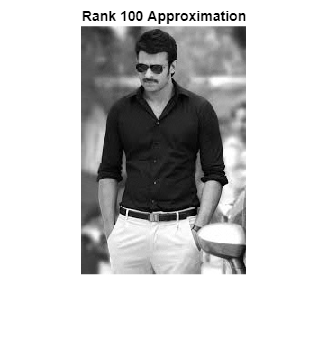

Rank 100: Compression Ratio = 1.0964


Relative Error: 0.011568


% Define ranks to test (adjust based on image size; e.g., full rank is min(size(A)))
ranks = [5, 20, 50, 100];  % Example values

% Get original dimensions
[m, n] = size(A);

% Loop over each rank
for i = 1:length(ranks)
    k = ranks(i);
    
    % Truncate matrices
    U_k = U(:, 1:k);
    S_k = S(1:k, 1:k);
    V_k = V(:, 1:k);
    
    % Reconstruct approximated image
    A_k = U_k * S_k * V_k';
    
    % Clip values to [0, 255] for display
    A_k = max(0, min(255, A_k));
    
    % Display the approximated image
    figure;
    imshow(uint8(A_k));
    title(['Rank ' num2str(k) ' Approximation']);
    
    % Optional: Calculate compression ratio
    % Original storage: m*n (pixels)
    % Compressed: k*(m + n + 1) (for U_k, V_k, S_k)
    compression_ratio = (m*n) / (k*(m + n + 1));
    disp(['Rank ' num2str(k) ': Compression Ratio = ' num2str(compression_ratio)]);
    
    % Optional: Calculate error (e.g., Frobenius norm)
    error = norm(A - A_k, 'fro') / norm(A, 'fro');
    disp(['Relative Error: ' num2str(error)]);
end

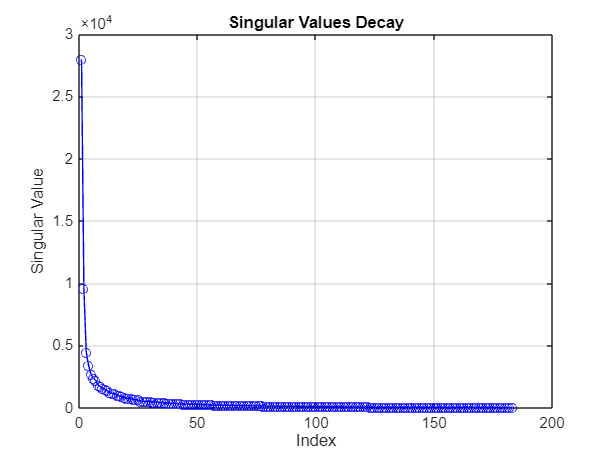

% Plot singular values
figure;
plot(singular_values, 'b-o');
xlabel('Index');
ylabel('Singular Value');
title('Singular Values Decay');
grid on;

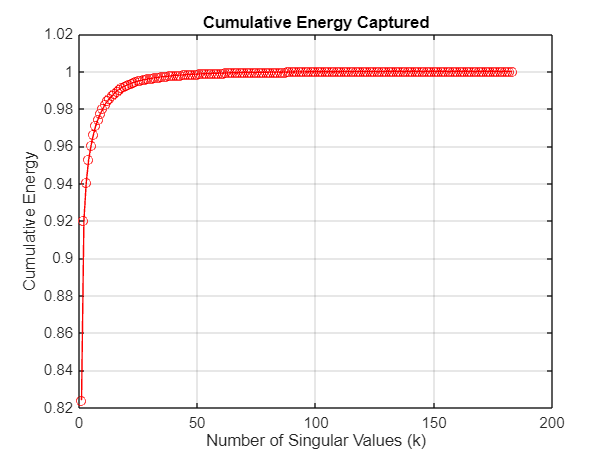


% Optional: Cumulative energy (fraction of total variance captured)
total_energy = sum(singular_values.^2);
cum_energy = cumsum(singular_values.^2) / total_energy;

figure;
plot(cum_energy, 'r-o');
xlabel('Number of Singular Values (k)');
ylabel('Cumulative Energy');
title('Cumulative Energy Captured');
grid on;

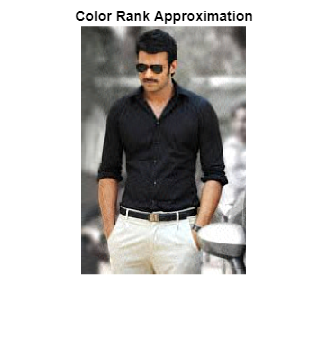

% Assuming img is RGB
R = double(img(:,:,1));
G = double(img(:,:,2));
B = double(img(:,:,3));

% SVD on each
[Ur, Sr, Vr] = svd(R);
[Ug, Sg, Vg] = svd(G);
[Ub, Sb, Vb] = svd(B);

% For a rank k
k = 50;  % Example
Rk = Ur(:,1:k) * Sr(1:k,1:k) * Vr(:,1:k)';
Gk = Ug(:,1:k) * Sg(1:k,1:k) * Vg(:,1:k)';
Bk = Ub(:,1:k) * Sb(1:k,1:k) * Vb(:,1:k)';

% Combine and display
img_k = cat(3, uint8(Rk), uint8(Gk), uint8(Bk));
figure;
imshow(img_k);
title('Color Rank Approximation');